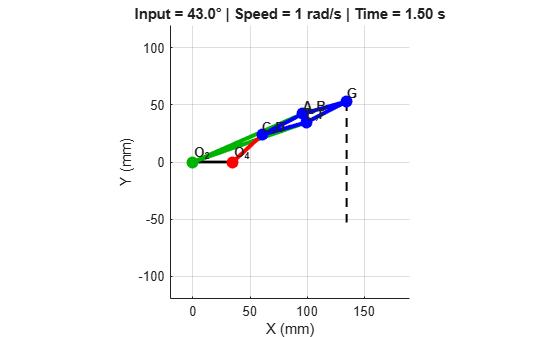

%% Peaucellier-Lipkin Mechanism
clear; clc; close all;

a = 105; b = 40; r = 35;       % Link dimensions (mm)
L = (a^2-b^2)/(2*r);
lim = 2*acos((a-b)/(2*r))-0.01;

omega = 1;                     % rad/s
dt = 0.01;
T = 2*lim/omega;
time = [0:dt:T, T];
theta = -lim + omega*time;

%% Figure
figure('Color','w');
hold on; axis equal; grid on;
xlim([-20 190]); ylim([-120 120]);
xlabel('X (mm)'); ylabel('Y (mm)');

O2 = [0;0]; O4 = [r;0];
ymax = L*tan(lim/2);

plot([O2(1) O4(1)],[0 0],'k-','LineWidth',2);
plot([L L],[-ymax ymax],'k--','LineWidth',1.5);

% Links 2–8: green, green, red, blue, blue, blue, blue
colors = [0 .7 0; 0 .7 0; 1 0 0; zeros(4,2) ones(4,1)];
links = gobjects(1,7);

for i = 1:7
    links(i) = plot(nan,nan,'-o','Color',colors(i,:), ...
        'LineWidth',3,'MarkerFaceColor',colors(i,:));
end

names = {'O_2','O_4','C,D','A,B','E,F','G'};
labels = gobjects(1,6);
for i = 1:6
    labels(i) = text(nan,nan,names{i},'FontWeight','bold');
end

%% Animation
clockStart = tic;

for k = 1:numel(time)
    t = theta(k);

    CD = [r*(1+cos(t)); r*sin(t)];
    G = [L; L*tan(t/2)];

    M = (CD+G)/2;
    d = norm(G-CD);
    h = sqrt(max(0,b^2-d^2/4));
    u = (G-CD)/d;
    v = [-u(2);u(1)];

    AB = M+h*v;
    EF = M-h*v;

    endpoints = {O2,AB; O2,EF; O4,CD; AB,CD; ...
                 CD,EF; AB,G; EF,G};

    for i = 1:7
        p = endpoints{i,1}; q = endpoints{i,2};
        set(links(i),'XData',[p(1) q(1)], ...
                     'YData',[p(2) q(2)]);
    end

    joints = [O2 O4 CD AB EF G];
    for i = 1:6
        set(labels(i),'Position',[joints(:,i)'+[0 7],0]);
    end

    title(sprintf('Input = %.1f° | Speed = 1 rad/s | Time = %.2f s', ...
    rad2deg(t), time(k)));
    drawnow;

    pause(max(0,time(k)-toc(clockStart)));
end


%% Results
fprintf('Output X = %.2f mm\n',L);

Output X = 134.64 mm


fprintf('Input range = +/- %.2f deg\n',rad2deg(lim));

Input range = +/- 43.00 deg


fprintf('Output stroke = %.2f mm\n',2*ymax);

Output stroke = 106.08 mm


fprintf('Sweep duration = %.2f s\n',T);

Sweep duration = 1.50 s


%% Velocity and Acceleration Analysis

syms theta omega alpha real

% Symbolic equations for output point P
y = L*tan(theta/2);
v = simplify(diff(y,theta)*omega);
acc = simplify(diff(v,theta)*omega + diff(v,omega)*alpha);

disp('Velocity:'); pretty(v)

Velocity:


$$\omega \,\left(\frac{1885\,{\tan\left(\frac{\theta }{2}\right)}^{2}}{28}+\frac{1885}{28}\right)$$

disp('Acceleration:'); pretty(acc)

Acceleration:


$$\frac{1885\,\left({\tan\left(\frac{\theta }{2}\right)}^{2}+1\right)\,\left(\tan\left(\frac{\theta }{2}\right)\,\omega^{2}+\alpha \right)}{28}$$

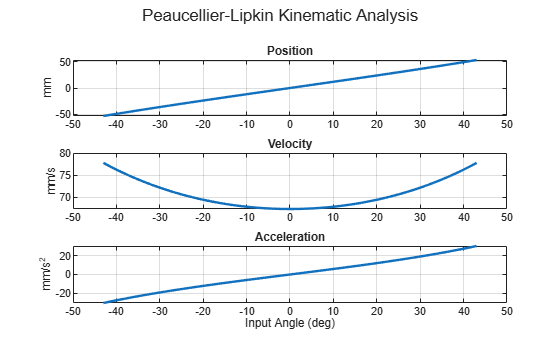


% Constant input angular velocity
w = 1;  % rad/s
t = linspace(-lim,lim,200);

% Numerical results
Y = L*tan(t/2);
V = (L/2)*sec(t/2).^2*w;
ACC = (L/2)*sec(t/2).^2.*tan(t/2)*w^2;

% Plot
figure('Color','w');
data = {Y,V,ACC};
names = {'Position','Velocity','Acceleration'};
units = {'mm','mm/s','mm/s^2'};

for i = 1:3
    subplot(3,1,i)
    plot(rad2deg(t),data{i},'LineWidth',1.8)
    grid on
    title(names{i})
    ylabel(units{i})
end

xlabel('Input Angle (deg)')
sgtitle('Peaucellier-Lipkin Kinematic Analysis')